clear; clc; close all;

✅ บันทึก segments_output_1\segment_01.mat (23500 ถึง 24499)
✅ บันทึก segments_output_1\segment_02.mat (26204 ถึง 27203)
✅ บันทึก segments_output_1\segment_03.mat (30945 ถึง 31944)
✅ บันทึก segments_output_1\segment_04.mat (34600 ถึง 35599)
✅ บันทึก segments_output_1\segment_05.mat (38734 ถึง 39733)
✅ บันทึก segments_output_1\segment_06.mat (42730 ถึง 43729)
✅ บันทึก segments_output_1\segment_07.mat (47229 ถึง 48228)
✅ บันทึก segments_output_1\segment_08.mat (51239 ถึง 52238)
✅ บันทึก segments_output_1\segment_09.mat (55678 ถึง 56677)
🎉 ตัดและบันทึกไฟล์ทั้งหมดเรียบร้อยแล้ว!


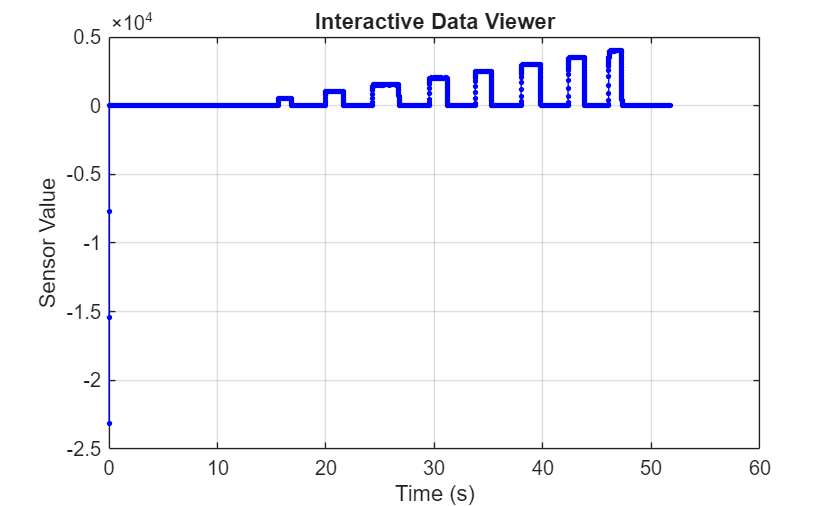


% โหลดข้อมูล
load('k4.mat');

% ถ้ามี timeseries อยู่ในตัวแปร data
if isa(data, 'timeseries')
    t = data.Time;
    y = data.Data;
else
    error('ไม่พบ timeseries "data" ในไฟล์นี้');
end

% ถ้า y เป็น 3 มิติ ให้บีบเหลือ 1 มิติ
y = squeeze(y);

% ตรวจสอบความยาว
if length(t) ~= length(y)
    warning('ความยาว t และ y ไม่ตรงกัน กำลังปรับให้สั้นเท่ากัน...');
    n = min(length(t), length(y));
    t = t(1:n);
    y = y(1:n);
end

% วาดกราฟ
figure;
plot(t, y, 'b.-', 'MarkerSize', 8);
xlabel('Time (s)');
ylabel('Sensor Value');
title('Interactive Data Viewer');
grid on;
hold on;

% เปิดโหมด data cursor
dcm = datacursormode(gcf);
set(dcm, 'UpdateFcn', @myupdatefcn);
datacursormode on;


% ------------------------------
% ฟังก์ชันแสดงค่าที่คลิก
% ------------------------------
function txt = myupdatefcn(~, event_obj)
    pos = event_obj.Position;
    txt = {['Index: ', num2str(event_obj.DataIndex)], ...
           ['Time: ', num2str(pos(1))], ...
           ['Value: ', num2str(pos(2))]};
end